# Trajectory Generation

**TASK: **Approximate the following trajectory using a set of points.

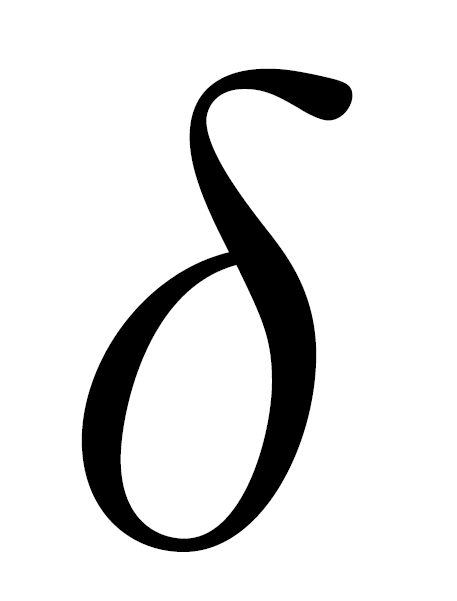

**STRATEGY:** First choose an adequate number of points in the xy plane and then rototranslate them, so that they lie in an inclined plane.

Dimensions are scaled with respect to a unitary box.

## Shape in the xy plane

#### Sampling points

P1 = [0.90; 0.60; 0]; % Home position
P = [[0.90; 0.07; 0] [0.72; 0.03; 0] [0.55; 0.03; 0] [0.44; 0.08; 0] [0.43; 0.18; 0] ...
     [0.56; 0.33; 0] [0.75; 0.52; 0] [0.75; 0.73; 0] [0.58; 0.92; 0] [0.38; 0.98; 0] ...
     [0.19; 0.94; 0] [0.06; 0.79; 0] [0.16; 0.58; 0] [0.34; 0.45; 0] [0.61; 0.38; 0]]; % Points along the trajectory

#### Curvilinear abscissa

dist = zeros(1,size(P,2));
for i = 2:size(P,2)
    dist(i) = dist(i-1) + norm(P(:,i)-P(:,1));
end

#### Spline interpolation

nPoints_spline = 50;
piecewise_poly = spline(dist(1,:),P(1:2,:));
spline_points = ppval(piecewise_poly,linspace(0,dist(end),nPoints_spline));
spline_points = [spline_points; zeros(1,nPoints_spline)];

#### Plot the sampled trajectory and the interpolated one

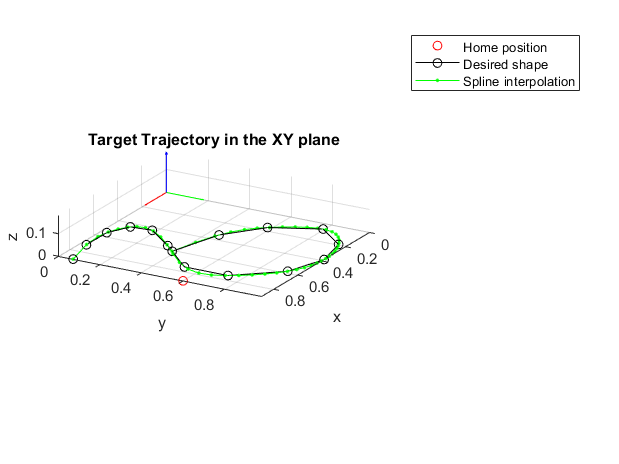

figure
p1 = plot3(P1(1),P1(2),P1(3),'or');
hold on
p2 = plot3(P(1,:),P(2,:),P(3,:),'k-o');
p3 = plot3(spline_points(1,:),spline_points(2,:),spline_points(3,:),'g.-');
grid on

frame_scaling_factor = 5;
plot_frame(eye(3),zeros(3,1),frame_scaling_factor)

axis equal
xlabel('x'); ylabel('y'); zlabel('z')
view(120,20)
title("Target Trajectory in the XY plane")
legend([p1 p2 p3], "Home position", "Desired shape", "Spline interpolation")

## Shape in the XYZ space

#### Specify target plane (rototranslation of the shape)

x_tilt = deg2rad(20);
y_tilt = deg2rad(30);
z_tilt = deg2rad(40);

x_offset = 0.1;
y_offset = 0.3;
z_offset = -0.4;

Rx = [1     0            0
      0 cos(x_tilt) -sin(x_tilt)
      0 sin(x_tilt)  cos(x_tilt)];
  
Ry = [ cos(y_tilt) 0 sin(y_tilt)
           0       1     0
      -sin(y_tilt) 0 cos(y_tilt)];
  
Rz = [cos(z_tilt) -sin(z_tilt) 0
      sin(z_tilt)  cos(z_tilt) 0
          0            0       1];
  
R = Rx*Ry*Rz;

T = [x_offset; y_offset; z_offset];

M_target = [  R   T
            0 0 0 1];
        
P1_homo = [P1; 1];        
P_homo = [P; ones(1,size(P,2))];    
P1_target = M_target*P1_homo;
P_target = M_target*P_homo;

spline_points_homo = [spline_points; ones(1,size(spline_points,2))]; 
spline_points_target = M_target*spline_points_homo;

#### Plot the final, rototranslated, shape of the trajectory (and the interpolated one)

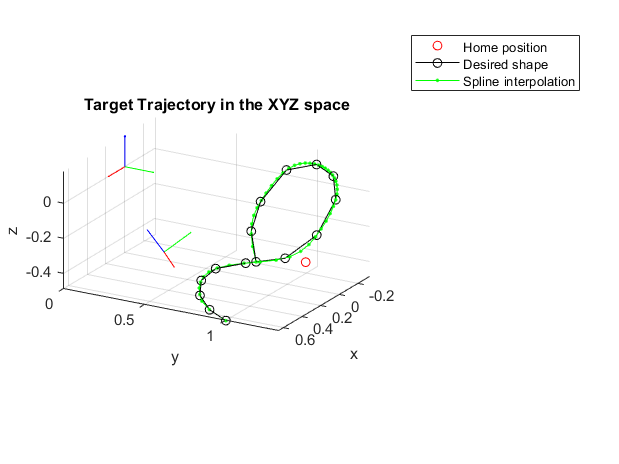

figure
p1 = plot3(P1_target(1),P1_target(2),P1_target(3),'or');
hold on
p2 = plot3(P_target(1,:),P_target(2,:),P_target(3,:),'k-o');
p3 = plot3(spline_points_target(1,:),spline_points_target(2,:),spline_points_target(3,:),'g.-');
grid on

plot_frame(eye(3),zeros(3,1),frame_scaling_factor)
plot_frame(R,T,frame_scaling_factor)

axis equal
xlabel('x'); ylabel('y'); zlabel('z')
view(120,20)
title("Target Trajectory in the XYZ space")
legend([p1 p2 p3], "Home position", "Desired shape", "Spline interpolation")